# **Métodos Númericos Aplicados I**

### Máster Universitario en Ingeniría Matemática y Computación

### Exámen Final

*Primer Cuatrimestre*

2) Resolución Gauss-Laguerre


$$\int_0^{+\inf } e^{-\sqrt{x}} \left(x-1\right)\mathrm{dx}\;$$


Cambio de variable


$$y=\sqrt{x}\Rightarrow x^{\frac{1}{2}} \;;\mathrm{dy}=\frac{1}{2*\sqrt{x}}\Rightarrow \frac{1}{2*y}\mathrm{dx}$$



$$\int_0^{+\inf } e^{-y} \left(y^2 -1\right)2y\;\;\mathrm{dy}\Rightarrow 2\int_0^{+\inf } e^{-y} \left(y^2 -1\right)y\;\;\mathrm{dy}\Rightarrow 2*\int_0^{+\inf } e^{-y} \;*\;y\left(y^2 -1\right)\mathrm{dy}\;\;\;$$



$$f\left(x_i \right)=\;\left(y^3 -y\right);$$


Función de Gauss-Laguerre

Implementación

[ci, xi] = Coeficientes_Nodos_Gauss_Laguerre(8)

ci =     0.3692
    0.4188
    0.1758
    0.0333
    0.0028
    0.0001
    0.0000
    0.0000


xi =     0.1703
    0.9037
    2.2511
    4.2667
    7.0459
   10.7585
   15.7407
   22.8631


f=@(y) y.*((y.^2) - 1);
I = 2.*sum(f(xi).*ci);
I

I = 10.0000

Comparamos con solución real:

g=@(x) exp(-sqrt(x)).*(x-1);
I_real = integral(g, 0, inf);
I_real

I_real = 10.0000

3)Resolución de la ecuación no Lineal:


$$f\left(x\right)=\sin \left(x\right)-x^2 +1$$


Usaremos Método de Newton y Traub-Otrowski

a) **Representación gráfica y valor aproximado**

x = 0:0.1:2

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y1 = sin(x)

y1 =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093


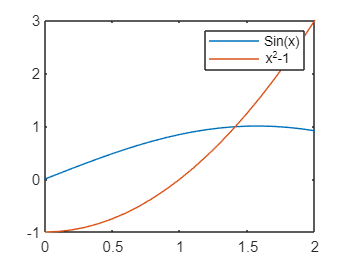

y2 = x.^2 - 1;
plot(x, y1, x, y2)
legend('Sin(x)', 'x^2-1')

**R .** El valor aproximado en que se cortan ambas funciones es:


$$x_0 =1\ldotp 4$$


b) Método de Newton

x0 = 1;

Tol = 1e-9

inc = incre1 + incre2

maxiter = 50

Aplicamosla función:

x0 = 1;
tol = 1e-9;
maxiter = 50;

[sol_Newton,iter_Newton,ACOC_Newton,inc_Newton] = Newton('NLE',x0,tol,maxiter)

$$sol\_Newton = 1.409624004$$

iter_Newton = 6

$$ACOC\_Newton = \left(\begin{array}{c} 1.860995974680093922870582900941371917724609375\\ 1.99539833324894289035000838339328765869140625\\ 2.00007092049128232247312553226947784423828125\\ \infty \end{array}\right)$$

$$inc\_Newton = 1.11022e-16$$

**x1** = $1.4096240$

**iters**=6

**inc final** = 1.11022e-16

**ACOC** = 2.000070

C) Implemetanción Traub-Ostrowski 

(**Final del documento**)

D) Aplicación método Traub-Ostrowski

[sol_TO,iter_TO,ACOC_TO,inc_TO] = TO('NLE',x0,tol,maxiter)

$$sol\_TO = 1.409624004$$

iter_TO = 4

$$ACOC\_TO = \left(\begin{array}{c} 3.21664981121290338705875910818576812744140625\\ 2.96343103058057977250427938997745513916015625 \end{array}\right)$$

$$inc\_TO = 6.11079e-11$$

**x1_TO** = $1.409624004$

**iter_TO** = 4

**ACOC_TO** = 2.963

**inc_TO** = $\text{6.11079e-11}$

E) Comparativa entre Newton y Traub Ostrowski

resultados = [sol_Newton,iter_Newton, inc_Newton, ACOC_Newton(end-1);
    sol_TO,iter_TO, inc_TO, ACOC_TO(end)];
% t = table(metodos', resultados(:,1), resultados(:,2),'VariableNames', ...
%     {'Metodo', 'Solución','Iteraciones', 'Inc', 'ACOC'});
disp(resultados)

$$\left(\begin{array}{cccc} 1.4096240040025962425573879954754374921321868896484375 & 6 & 0.00000000000000011102230246251565404236316680908203125 & 2.00007092049128232247312553226947784423828125\\ 1.4096240040025962425573879954754374921321868896484375 & 4 & 0.00000000006110789652069570365711115300655364990234375 & 2.96343103058057977250427938997745513916015625 \end{array}\right)$$

Encontrarmos que ambos métodos convergen en la solución esperada, además que alcanzan el orden téorico establecido. Newton con orden p= 2.000 y TO con orden p = 3. 

El métodp TO alcanza la convergencia en menos iteraciones que Newton 

iter_TO = 4; Iter_Newton= 6

Por tabto I_TO > I_Newton

function [fun,dfun] = NLE(x)
fun = sin(x) - x.^2 + 1;
dfun = cos(x) - 2.*x;
end

function [sol,iter,ACOC,inc] = Newton(fun,x0,tol,maxiter)
digits(200)
x0=x0(:);
iter=0;
[fx0,dfx0]=feval(fun,x0);
incre1=tol+1;
incre2=tol+1;
p=[];
inc = incre1 + incre2;
% while incre2>tol && incre1>tol && iter<maxiter
while inc > tol && iter<maxiter
    
    %Linea NEWTON
    x1=x0-fx0/dfx0;
    %
    
    %actualizo criterio de parada
    incre1=norm(x1-x0);
    p=[p incre1];
    x0=x1;
    [fx0,dfx0]=feval(fun,x0);
    incre2=norm(fx0);
    iter=iter+1;
    inc = incre1 + incre2;
end
% calculo de ACOC
ACOC=log(p(3:end)./p(2:end-1))./log(p(2:end-1)./p(1:end-2));

sol=x1;
incre1=vpa(incre1,6);
incre2=vpa(incre2,6);
inc = vpa(inc, 6);
ACOC=vpa(ACOC,6);
ACOC=ACOC(:);
sol=vpa(sol,10);
end

function [sol,iter,ACOC,inc] = TO(fun,x0,tol,maxiter)
digits(200)
x0=x0(:);
iter=0;
[fx0,dfx0]=feval(fun,x0);
incre1=tol+1;
incre2=tol+1;
p=[];
inc = tol +1;
% while incre2>tol && incre1>tol && iter<maxiter
while inc > tol && iter<maxiter
    
    %Linea Ostrowski
    y0 = x0 - (fx0/dfx0);
    [fy0, dfy0] = feval(fun, y0);
    x1=y0-(fx0 / (fx0 - 2*fy0))*(fy0/dfy0);
    %
    
    %actualizo criterio de parada
    incre1=norm(x1-x0);
    p=[p incre1];
    x0=x1;
    [fx0,dfx0]=feval(fun,x0);
    incre2=norm(fx0);
    iter=iter+1;
    inc = incre1 + incre2;
end
% calculo de ACOC
ACOC=log(p(3:end)./p(2:end-1))./log(p(2:end-1)./p(1:end-2));

sol=x1;
incre1=vpa(incre1,6);
incre2=vpa(incre2,6);
ACOC=vpa(ACOC,6);
ACOC=ACOC(:);
inc = vpa(inc, 6);
sol=vpa(sol,10);
end



Calculos de los Nodos y función de calculo

function [ci, xi] = Coeficientes_Nodos_Gauss_Laguerre(n)
%Con esta función de Matlab vamos a calcular los coeficientes y los 
%nodos para la cuadratura de Gauss-Laguerre. 

%La variable de entrada es el número de nodos que queremos calcular: n

%Las variables de salida son los coeficientes (ci) y los nodos (xi)

%--------------------------------------------------
%Definimos la variable simbólica
syms x 

%Definimos los dos primeros polinomios: (como matlab no puede trabajar 
%                                        con la componente 0 empezamos con
%                                        la primera)
pk=1;
pk1=(1-x);
%(En los polinomios añadimos una unidad porque matlab no trabaja con la componente 0)
%Calculamos un polinomio más que el número de nodos para los coeficientes
for k=0:n-1
    pk2=simplify((2*k+3-x).*pk1-(k+1)^2.*pk);
    pk=pk1;
    pk1=pk2;
end
xi=double(solve(pk==0));
ci=(factorial(n)^2.*xi)./(double(subs(pk1,x,xi)).^2);
end
